1.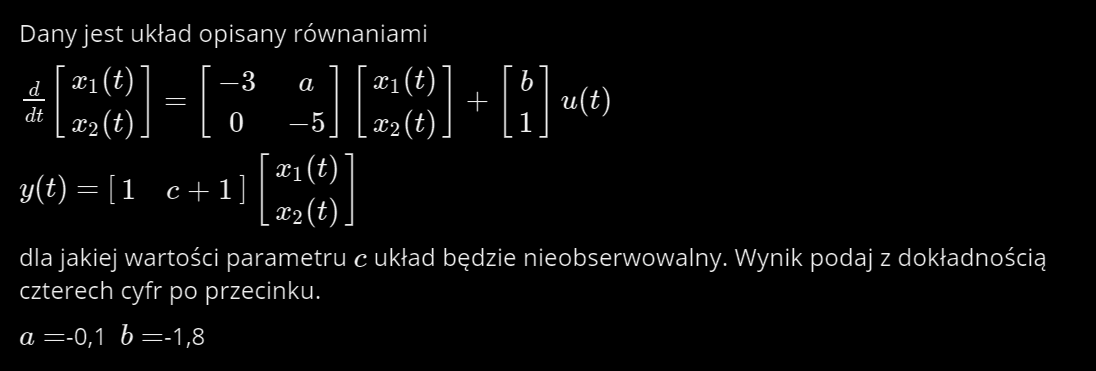

syms c;
a=-0.1;
b=-1.8;
A=[-3,a;0,-5];
B=[b;1];
C=[1,c+1];
O=[C;C*A];
double(solve(det(O)==0,c))

ans = -1.0500

2.

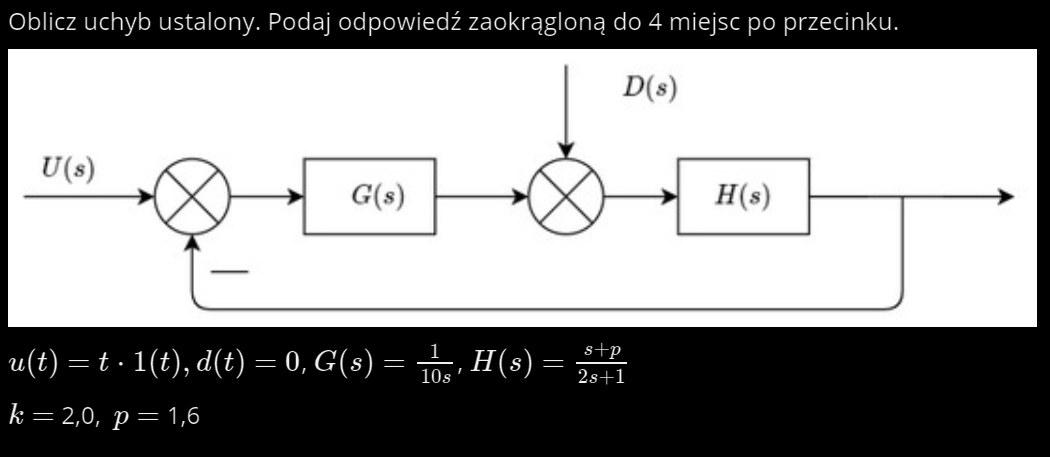

k=2;
p=1.6;
syms S(s) s t
G=1/10/s;
H=(s+p)/(2*s+1);
D=0;
U=laplace(t);
G0=(G+D)*H;
E=simplify(1/(1+G0));
S(s)=simplify(E*U*s);
double(S(0))

ans = 6.2500

3.

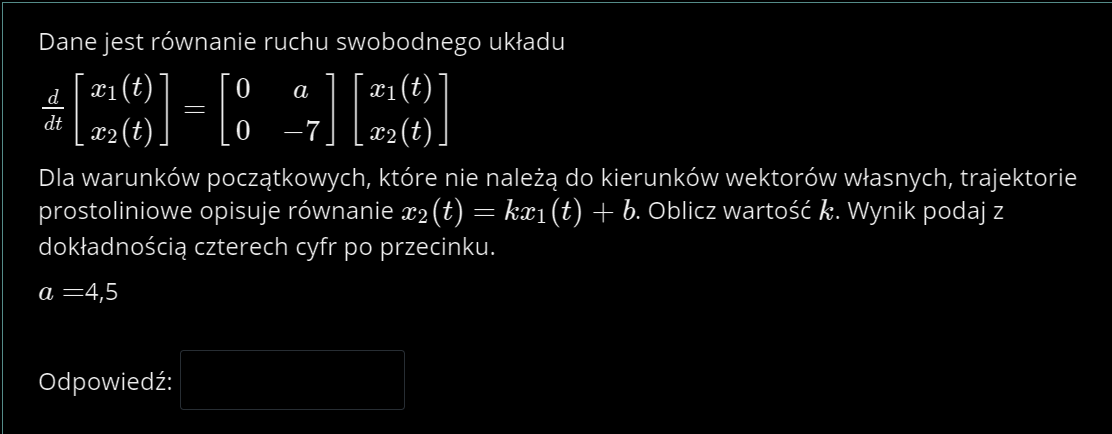

a=4.5;
A=[0,a;0,-7];
[V,s]=eig(A);

syms x1 x2;
x=[x1;x2];
solve(det([V(:,1) x]),x2)

$$ans = 0$$

solve(det([V(:,2) x]),x2)

$$ans = -\frac{14\,x_{1}}{9}$$

-14/9

ans = -1.5556

4.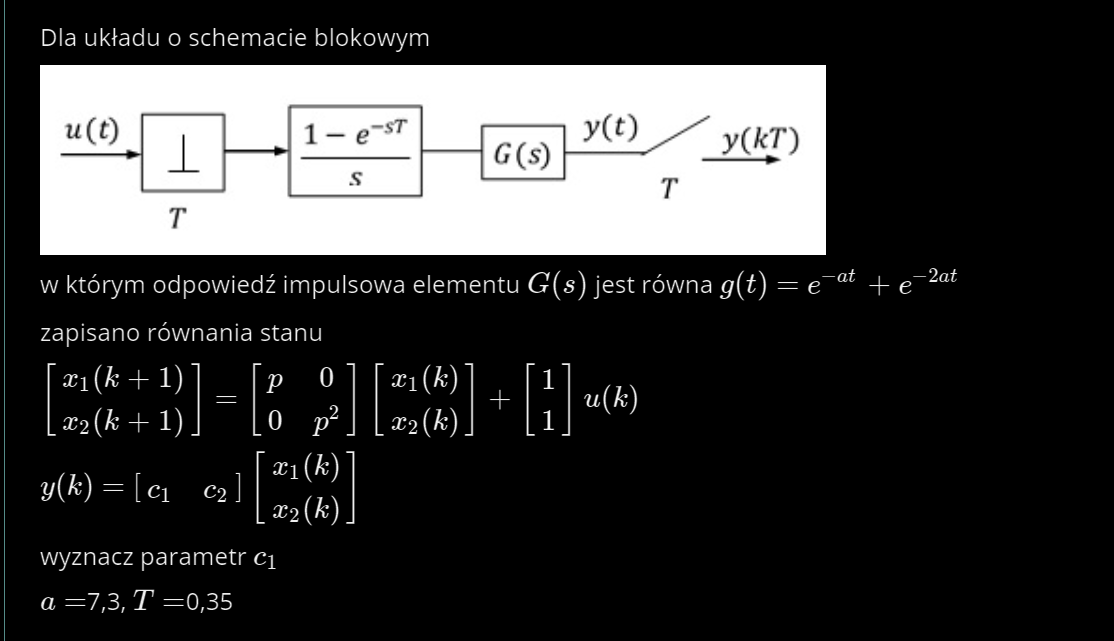

T=0.35

T = 0.3500

a=7.3;
syms s z t n b g(t);
gg=exp(-a*t)+exp(-2*a*t);
G=laplace(gg)

$$G = \frac{1}{s+\frac{73}{5}}+\frac{1}{s+\frac{73}{10}}$$

E=(1-exp(-T*s))/s;
G=G;
g(t)=ilaplace(G);
Gz=simplify(ztrans(g(n*T)))

$$Gz = \frac{z}{z-{\mathrm{e}}^{-\frac{511}{100}}}+\frac{z}{z-{\mathrm{e}}^{-\frac{511}{200}}}$$

[num, den]=numden(Gz);
n=sym2poly(num)

n = 	1.0e+03 *

    4.2648   -0.1785         0


d=sym2poly(den)

d = 	1.0e+03 *

    2.1324   -0.1785    0.0010


roots(d)

ans =     0.0777
    0.0060


5.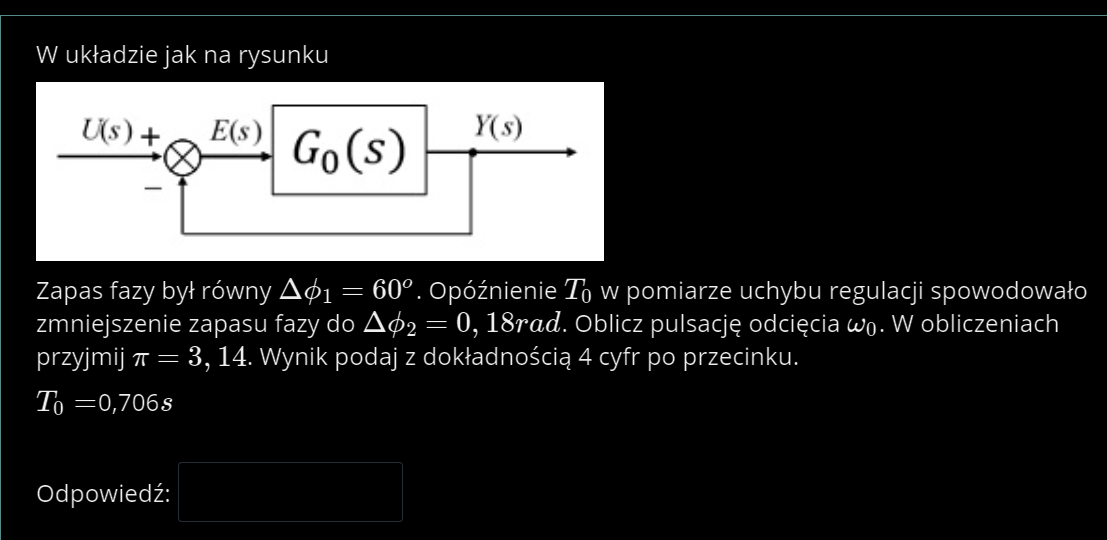

T0=0.706;
syms w0
PI=3.14;
dphi1=60*PI/180;
dphi2=0.18;
T01=dphi1/w0;
T02=dphi2/w0;
double(solve(T0==T01-T02,w0))

ans = 1.2276

6.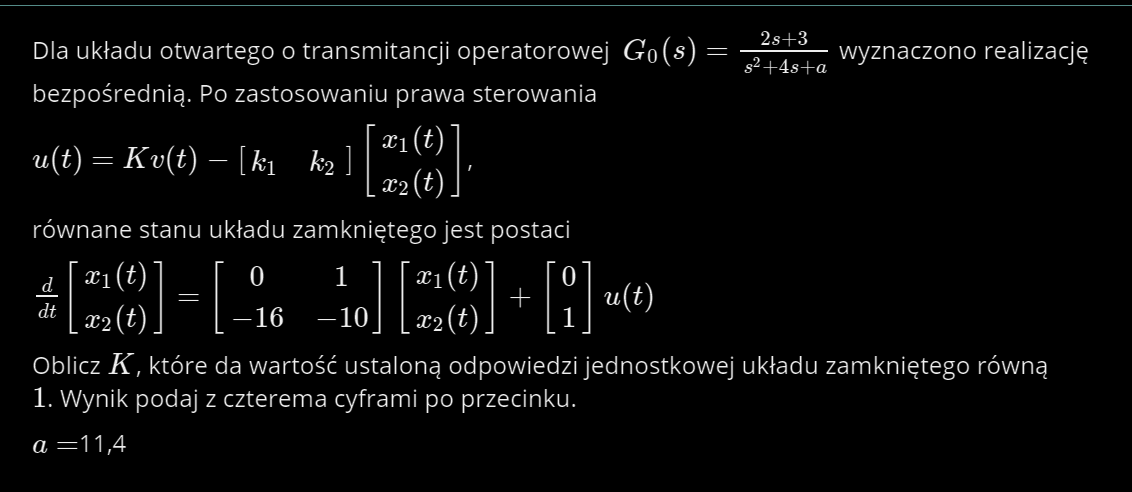

a=11.4;
A=[0,1;-a,-4];
B=[0;1];
C=[3,2];
Az=[0,1;-16,-10];
syms G(s) K;
G(s)=C*inv(eye(2)*s-Az)*B*K;
double(solve(G(0)==1,K))

ans = 5.3333